# Marble Rolling on Circular Surface (with event)

## Problem Statement

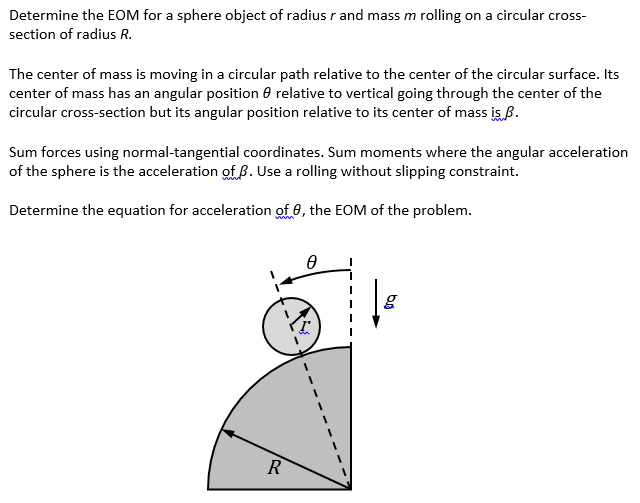

## Step 1: Conceptualize The Problem

Find the angular displacement of the mass as a function of time by determining the EOM and numerically integrating using ode45. 

- 1 degree of freedom

- Gravity is acting

- Mass rolls without slip

## Step 2: Coordinate System

## Step 3: Free-Body Diagram

## Step 4: Fundamental Equations

clear
clc
syms m g R r I theta theta_dot theta_ddot beta_ddot N f
c.m = 1; % kg
c.R = 0.5; % m
c.r = 0.05; % m
c.g = 9.81; % m/s^2
Icm = 2/5*m*r^2; % for sphere
eqn(1) = m*g*cos(theta)-N == m*(R+r)*theta_dot^2;
eqn(2) = m*g*sin(theta)-f == m*(R+r)*theta_ddot;
eqn(3) = r*f == Icm*beta_ddot;
eqn

$$eqn = \left(\begin{array}{ccc} g\,m\,\cos\left(\theta \right)-N=m\,{\dot{\theta }}^{2}\,\left(R+r\right) & g\,m\,\sin\left(\theta \right)-f=m\,\ddot{\theta }\,\left(R+r\right) & f\,r=\frac{2\,\ddot{\beta }\,m\,r^{2}}{5} \end{array}\right)$$

## Step 5: Knowns and Unknowns

### Knowns


$$m, g, r, R, I_{cm}$$


### Unknowns

$\theta$: angular position of center of mass (measured from vertical)

$\beta$: rotation angle of disk (measured from vertical)

$N$: normal force

$f$: friction force

## Step 6: Constraints

Constraints between acceleration components.

eqn(4) = [beta_ddot] == (R+r)/r*theta_ddot;

Now have 4 eqs and 4 unknowns.

## Step 7: Obtain the EOMs

### Nonlinear EOMs

unknowns = solve(eqn,[theta_ddot,beta_ddot,N,f]);
theta_ddot = simplify(unknowns.theta_ddot)

$$theta\_ddot = \frac{5\,g\,\sin\left(\theta \right)}{7\,\left(R+r\right)}$$

beta_ddot = simplify(unknowns.beta_ddot)

$$beta\_ddot = \frac{5\,g\,\sin\left(\theta \right)}{7\,r}$$

N = simplify(unknowns.N)

$$N = -m\,\left(R\,{\dot{\theta }}^{2}-g\,\cos\left(\theta \right)+r\,{\dot{\theta }}^{2}\right)$$

f = simplify(unknowns.f)

$$f = \frac{2\,g\,m\,\sin\left(\theta \right)}{7}$$

## Step 8: Solve the EOMs

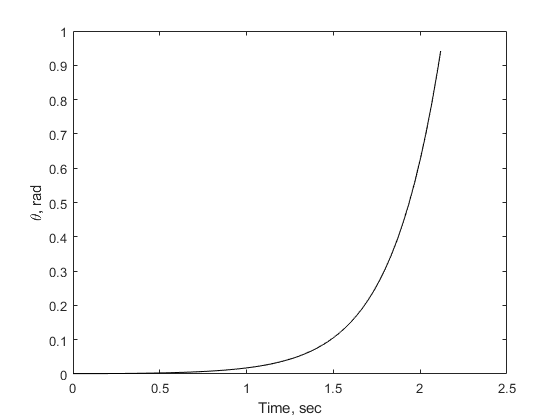

options = odeset('Events',@(t,s)event(t,s,c));
[T,S,TE,SE] = ode45(@(t,s)eom(t,s,c),linspace(0,10,301),[0.001,0],options);
plot(T,S(:,1),'-k')
xlabel('Time, sec')
ylabel('\theta, rad')

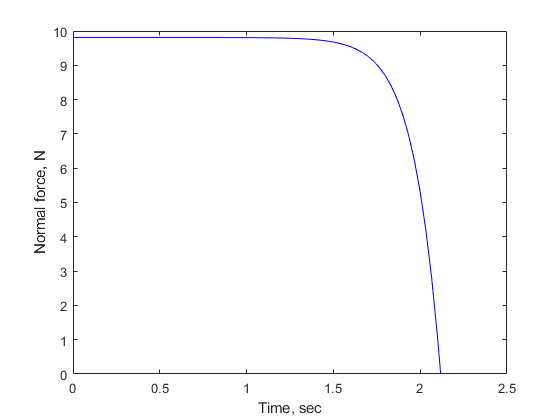

Nplot = c.m*c.g*cos(S(:,1))-c.m*(c.R+c.r)*S(:,2).^2;
plot(T,Nplot,'-b')
xlabel('Time, sec')
ylabel('Normal force, N')

fprintf('Final theta angle is %4.3f rad or %4.2f deg \n',SE(1,1),SE(1,1)*180/pi)

Final theta angle is 0.942 rad or 53.97 deg 


function ds = eom(t,s,c)
    ds(1,1) = s(2);
    ds(2,1) = 5/7*c.g/(c.R+c.r)*sin(s(1));
end
function [value,isterminal,direction] = event(t,s,c)
    value = c.m*c.g*cos(s(1))-c.m*(c.R+c.r)*s(2)^2; % equation to represent event (in this case its N)
    isterminal = 1; % stop when event occurs = true
    direction = -1; % which delta value matters (in this case N is decreasing)
end

## Step 9: Does It Make Sense?

### Units

### Magnitudes

### Signs

## Appendix

### Contributions

who did what...

### Attachments

EOMs derived during class lecture.